# Introduction

TopoToolbox provides a set of MATLAB functions that support the analysis of relief and flow pathways in digital elevation models (DEMs). The major aim of TopoToolbox is to offer helpful analytical GIS utilities in a non-GIS environment in order to support the simultaneous application of GIS-specific and other quantitative methods. 

TopoToolbox is written in the MATLAB language and requires the Image Processing Toolbox. In addition, the Mapping Toolbox is recommended as it enables working with different cartographic projections and simplifies data exchange (reading of geotiffs, reading and writing of shapefiles).

In addition, some functions require the Statistics and Machine Learning Toolbox or the Optimization Toolbox. Some functions see some speed-up if you have the Parallel Computing Toolbox.

## About the User Guide

This user guide is intended as a basic introduction to the TopoToolbox. It won't give a comprehensive overview on the functions available but serves a documentation for a simple session. In addition, this user guide provides an account for the command-line based tools of TopoToolbox only. It does not expand upon the use of the GUIs.

## Classes and objects in TopoToolbox

TopoToolbox has an object-oriented program design. Hence, TopoToolbox' functionalities are organized into computational classes that describe three main objects: GRIDobj, FLOWobj, and STREAMobj. In addition, there is SWATHobj, and others will follow in the future. Here, we will focus on the first three of these objects.

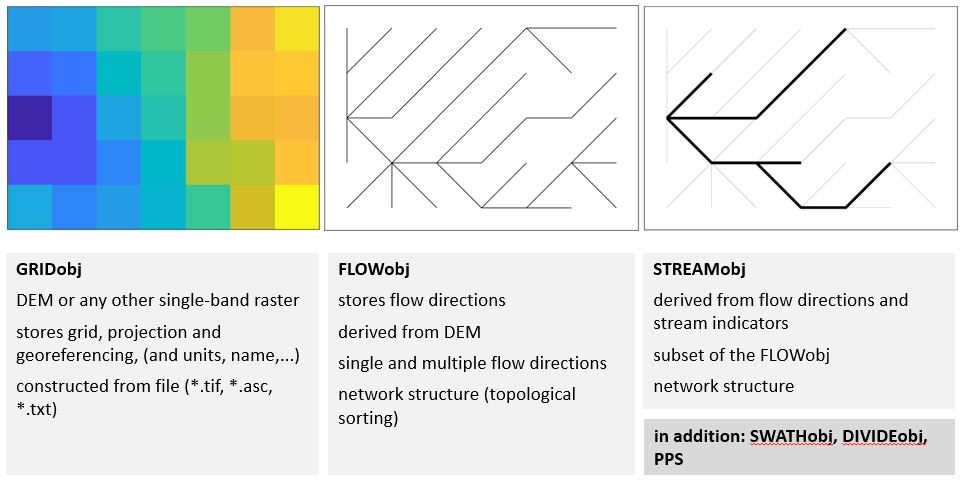

GRIDobj is the class used to store digital elevation models, but also other single-band rasters. The values contained in an instance of GRIDobj consist of a rectangular array of elevation values and information on spatial referencing (e.g. coordinate reference system, cellsize, ...). In object-oriented programming, these values are referred to as properties. The GRIDobj class is associated with numerous functions, or methods. As an example, gradient8 is a method associated with GRIDobj and calculates the slope of a digital elevation model.

FLOWobj is the class which stores flow directions, which are derived from a GRIDobj. An instance of FLOWobj stores the flow network together with additional information on spatial referencing. Most GIS software store flow directions as grid, but there are many reasons why TopoToolbox provides an extra class. The most important one is computational efficiency.

Finally, a STREAMobj is derived from a FLOWobj. An instance of this class stores the stream network, which represents the channelized part of the landscape or any other discrete flow path. 

These three main classes have a procedural hierarchy: Usually, you will start with a digital elevation model, derive flow directions and compute the stream network. However, at some stage, you will work on tasks in which these objects interact with each other. Methods associated with STREAMobj will use or return instances of GRIDobj, and vice versa. The linear work flow will thus evolve into a workflow in which TopoToolbox' classes will interact.

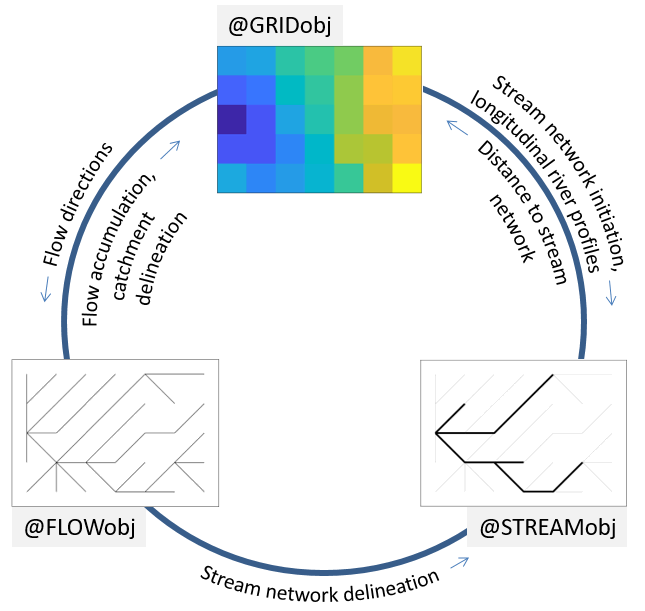 

## Load a DEM into Matlab

TopoToolbox reads the ESRI ascii grid format and single band geotiffs into an instance of GRIDobj.

**Note that, most functions in TopoToolbox assume that the DEM has a projected coordinate system (e.g. UTM WGS84) and that elevation values and horizontal coordinates have the same length units (preferably in meter).**

DEM = GRIDobj('srtm_bigtujunga30m_utm11.tif');

DEM is now an instance of the class `GRIDobj`. DEM contains various properties which include an array of the elevation data and information on the spatial referencing of the grid.

DEM

The actual elevation raster is stored in the property `.Z`. You can access it using linear indexing, subscripts or logical indexing as you are used to do with standard MATLAB matrices and arrays. For example, to extract the upper-left 5x5 pixel in the grid run following command.

DEM.Z(1:5,1:5)

GRIDobj is associated with various methods. Some of these methods overwrite existing builtin functions (e.g. `plus`, `minus`, `isnan`).  Here is an overview of the methods (functions) that can be called with an instance of GRIDobj.

methods GRIDobj

## View the DEM

Matlab provides numerous ways to display gridded data (images). Among these are `imagesc`, `surf`, `pcolor`, `imshow`, etc. TopoToolbox overwrites only `imagesc` and `surf`

imagesc(DEM)

Note that the axes contain the x and y coordinates and that the axes are scaled equally.

Another useful function is imageschs which displays an instance of `GRIDobj` and overlays it with the DEM. Here we display the slope (see function `gradient8`) together with the hillshade calculated from DEM. For visualization purposes the color range clips slopes that exceed 1 m/m.

G = gradient8(DEM);
imageschs(DEM,G,'ticklabel','nice','colorbarylabel','Slope [-]','clim',[0 1])

If none of the available visualization functions do what you are looking for, you can simply convert your DEM to the basic numeric classes using `GRIDobj2mat`. The function returns two coordinate vectors and a matrix with values. Here we crop our DEM to a smaller extent before plotting.

DEMc = crop(DEM,sub2ind(DEM.size,[1 50],[1 50]));
[Z,x,y] = GRIDobj2mat(DEMc);
surf(x,y,double(Z))

Note: See the help of the function `crop` on other ways to clip your data to a desired extent.

## Topographic attributes

Topographic attributes are derivatives obtained from a DEM such as slope, exposition or curvature. We assume that you are familiar with the meaning of these attributes and you will notice must of the functions by their function name such as

- `gradient8` -> as opposed to the MATLAB builtin gradient function, `gradient8` calculates the downward gradient in 8 possible directions for each cell and takes the maximum.

- `curvature` -> the second derivative of a DEM measures how surface slope change either along downward (profile curvature) or contour parallel direction (planform curvature).

- `roughness` -> allows you calculate various roughness indices related to intercell, topographic variability such as ruggedness etc.

- `aspect` -> slope exposition

- and many more

## Export an instance of GRIDobj to the disk

TopoToolbox ships with two functions for writing instances of GRIDobj back the hard drive so that they can be read by standard GIS software such as ArcGIS etc.

GRIDobj2ascii(DEMc,'test.txt');
GRIDobj2geotiff(DEMc,'test.tif');

Note that writing geotiffs is possible without having the mapping toolbox available. However, TopoToolbox will then write an image with a tfw-file (worldfile) which will be used by other GIS software to georeference the grid. Yet, the grid won't have a projection which must then be defined in GIS. See help `GRIDobj2geotiff` for details.

## Fill sinks

Often DEMs contain erroneous topographic depressions that should be filled prior to flow path computation. You can fill sinks using the function `fillsinks`. Note that in some situations it is more appropriate to not fill sinks but to carve the DEM which will be shown below (see section on `FLOWobj`). Hence, different to most GIS software, sink filling is usually not required when working with TopoToolbox.

DEMf = fillsinks(DEM);
imageschs(DEM,DEMf-DEM)

## FLOWobj and flow related functions

TopoToolbox 3 uses a novel technique to store flow direction that allows for easy coding and fast performance and follows the algorithm outlined in Schwanghart et al. (2013). Flow directions are stored as an object called `FLOWobj`, an instance of which is derived from an existing DEM (instance of `GRIDobj`).

Here is a fast way to calculate flow accumulation based on the previously sink filled DEM. The flow accumulation grid is dilated a little bit, so that flow paths are more easily appreciated in the figure.

FD = FLOWobj(DEM);
A  = flowacc(FD);
imageschs(DEM,dilate(sqrt(A),ones(5)),'colormap',flowcolor,...
    'colorbarylabel','Flow accumulation [sqrt(# of pixels)]',...
    'ticklabel','nice');

When creating an instance of `FLOWobj`, you can set numerous options that are summarized in the help of `FLOWobj`. 

## Methods associated with FLOWobj

Various methods exist that operate on instances of FLOWobj to obtain flow related variables such as drainage basin delineation, flow accumulation, etc. Here is an overview

methods FLOWobj

Now, let's calculate the drainage basins of the DEM. This can be done using the function `drainagebasins`. You may want to shuffle the colors so that the drainage basins can be more easily distinguished in a plot (`shufflelabel`). As a small exercise, let's denote the area of each basin in the map. 

DB = drainagebasins(FD);
DB = shufflelabel(DB);

Easy until here. Now let's get the area and display it together with the drainage basins map. To avoid overlapping labels, let's display only numbers for drainage basins larger than 10 km^2.

nrDB = numel(unique(DB.Z(:)))-1; % nr of drainage basins
STATS = regionprops(DB.Z,'PixelIdxList','Area','Centroid');

imageschs(DEM,DB,'colorbar',false,'ticklabel','nice');

hold on
for run = 1:nrDB
    if STATS(run).Area*DB.cellsize^2 > 10e6
        [x,y] = ind2coord(DB,...
            sub2ind(DB.size,...
            round(STATS(run).Centroid(2)),...
            round(STATS(run).Centroid(1))));
        text(x,y,...
            num2str(round(STATS(run).Area * DB.cellsize^2/1e6)),...
            'BackgroundColor',[1 1 1]);
    end
end
hold off


It may also be interesting to know the distance from each drainage basin outlet in upstream direction along the flow network.

D = flowdistance(FD);
D = D/1000;
imageschs(DEM,D,'ticklabel','nice','colorbarylabel','Flow distance [km]')

You can use the output of flowdistance to calculate the area function which is the frequency distribution of flow distances to the outlet of a specific basin. Let's take the largest basin in our study site.

% Identify the basin with the largest area
[~,IX] = max([STATS.Area]);
% Extract the distance values for the largest basin and calculate the
% histogram
histogram(D.Z(DB.Z == IX),'Normalization','pdf');
xlabel('Distance to outlet [lm]');
ylabel('# cells');

## STREAMobj - a class for stream networks

While FLOWobj stores the information on the entire flow network on hillslopes and in channels, STREAMobj is a class that is used to analyze the channelized part of the flow network only. The storage strategy is very similar to the one of the class FLOWobj.

Again, various methods (functions) are associated with STREAMobj that allow for manipulating, plotting and retrieving information on the stream network geometry and patterns.

There are various ways to extract the channelized flow network from DEMs. In this example we simply use an area threshold.

% calculate flow accumulation
A = flowacc(FD);
% Note that flowacc returns the number of cells draining
% in a cell. Here we choose a minimum drainage area of 10000 cells.
W = A>10000;
% create an instance of STREAMobj
S = STREAMobj(FD,W);
% and plot it
plot(S);
axis image

STREAMobj stores various properties some of which you might use to directly access if you want to customize your code or build your own functions. Please check the help of STREAMobj.

Like the other TopoToolbox objects, STREAMobj are associated with numerous methods that enable modifying the geometry of the stream network, to extract trunk streams, to smooth, etc. An overview is again listed by the command

methods STREAMobj

Now let's extract the largest subnetwork of the channel network 

S = klargestconncomps(S,1);
plot(S); axis image

and plot flow distance along the stream network versus elevation.

plotdz(S,DEM)

If you have a license of MATLAB's Mapping Toolbox you can export the stream network to a shapefile to be read by other GIS software. First, you need to create a mapstruct, a structure array used by the mapping toolbox to store vector data. Then use shapewrite to write the mapstruct to a shapefile.

MS = STREAMobj2mapstruct(S);
shapewrite(MS,'testshape.shp')

## References

Schwanghart, W., Groom, G.B., Kuhn, N.J., Heckrath, G.  (2013): Flow network derivation from a high resolution DEM in a low  relief, agrarian landscape. Earth Surface Processes and Landforms, 38, 1576-1586. [DOI: [10.1002/esp.3452](http://dx.doi.org/10.1002/esp.3452)]

Schwanghart, W., Scherler, D. (2014): TopoToolbox 2 – MATLAB-based software for topographic analysis and modeling in Earth surface sciences. Earth Surface Dynamics, 2, 1-7. [DOI: [10.5194/esurf-2-1-2014](http://dx.doi.org/10.5194/esurf-2-1-2014)]

Schwanghart, W., Kuhn, N.J. (2010): TopoToolbox: a set of Matlab functions for topographic analysis. Environmental Modelling & Software, 25, 770-781. [DOI: [10.1016/j.envsoft.2009.12.002](http://dx.doi.org/10.1016/j.envsoft.2009.12.002)]

clear